callHarmonics

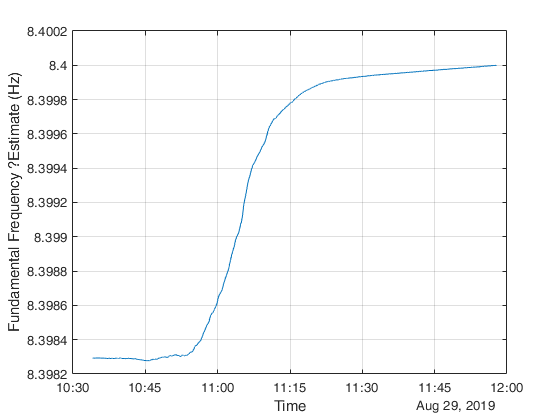

clear
tog.VOI = 'DesGros-AAA1-29Aug19';
[fileTime, par.AOI, NWFile, par.shipName, par.dataYear, par.mmsi] = shipLoader(tog.VOI);
load(NWFile);
x = data(:,1); clear data
par = setPars;
CFR = 8.4;

%fileStart = datenum(time(1));
startTime = time(1);
endTime = startTime + seconds(length(x)/par.fs);
TimeVector = startTime:seconds(1/par.fs):endTime;
%fileStart = time(1);
%TimeVector = fileStart:1/par.fs/(3600*24):fileStart+length(x)/par.fs;
TimeVector = TimeVector(1:end-1);
[theta, theta_curve] = harmonic_est(x,50,2500,CFR);

figure
plot(TimeVector,flip(2*pi/par.fs*theta_curve))
% hold on
% plot(tm,true,'r--','LineWidth',3)
grid on
xlabel('Time')
ylabel('Fundamental Frequency ?Estimate (Hz)')

% legend('Tracking','True')
% subplot(212)
% [H,F]=freqz(b,a,N,Fs);
% plot(F,log10(abs(H)))
% title('Final Comb Filter')
% xlabel('Frequency')
% ylabel('Magnitude')


% clear all;close all;clc
% N=1200;
% Fs=8000;
% tm=[0:1/Fs:(N-1)/Fs]';
% t=[0:400:N]+1;
% snr=10^(-18/20);
% F=[1000 1075 975];
% x=[];
% true=[];
% for i=1:3
%     T=2*pi*F(i).*tm(t(i):t(i+1)-1);
%     sig=sin(T)+0.5*cos(T*2)+0.25*cos(T*3)+randn(N/3,1).*snr;
%     x=[x;sig];
%     true=[true;ones(N/3,1)*F(i)];
% end
% 
% [theta,theta_curve,b,a]=harmonic_est(x,3,Fs);
% subplot(211)
% plot(tm,theta_curve)
% hold on
% plot(tm,true,'r--','LineWidth',3)
% grid on
% xlabel('Time')
% ylabel('Fundamental Frequency Estimate')
% legend('Tracking','True')
% subplot(212)
% [H,F]=freqz(b,a,N,Fs);
% plot(F,log10(abs(H)))
% title('Final Comb Filter')
% xlabel('Frequency')
% ylabel('Magnitude')

% 